# Entrega4

% Joan Manuel Ramos Refusta + Borja Cantero Aranda


## Exercici 1:

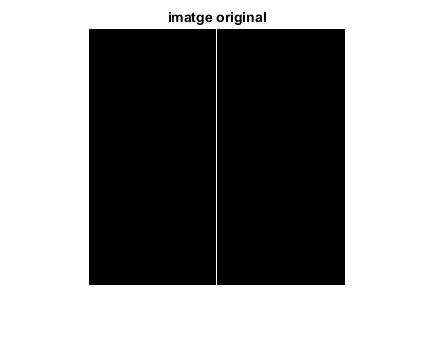

% Dilatar la imatge utilitzant EE [1 1 1]

im = false(256);
im(:,128)=1;
imshow(im),title('imatge original')

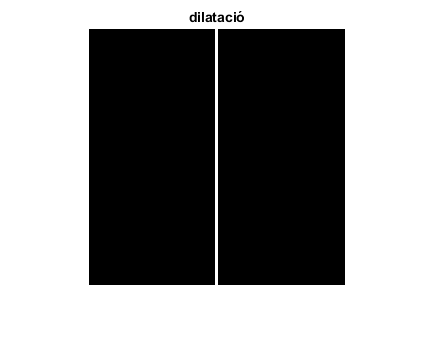


ee = [1 1 1];
res = false(256);

% Bucle sobre la matriu imatge i quan trobem un valor a 1 (blanc) apliquem
%l'element estructurant

for i=1:256
    for j=1:256
        if (im(i,j) == 1)
            res(i,j-1:j+1) = ee;
        end
    end
end
figure,imshow(res),title('dilatació')

## Dilatació

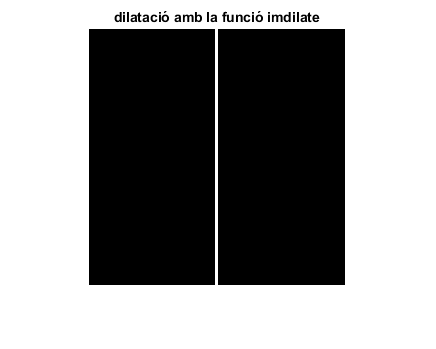

dil=imdilate(im,ee);
figure,imshow(dil),title('dilatació amb la funció imdilate')

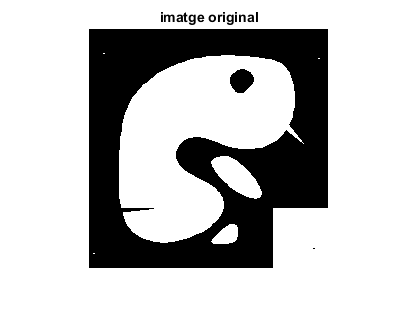


im=imread('blob.tif');
figure,imshow(im),title('imatge original')

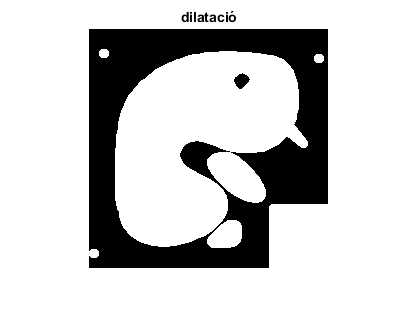


ee = strel('disk', 5);
dil = imdilate(im,ee);
ero=imerode(im,ee);

% Dilatació
figure,imshow(dil),title('dilatació')

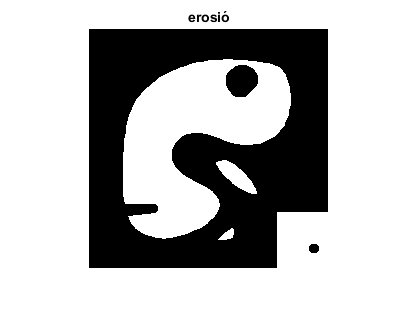


% Erosió
figure,imshow(ero),title('erosió')

## Open i close

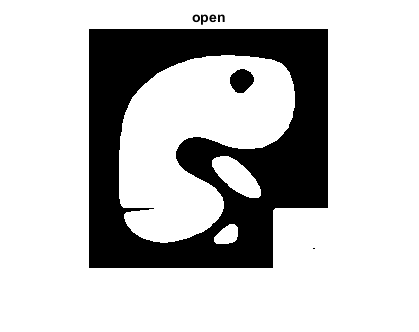

op = imopen(im,ee);
cl=imclose(im,ee);
figure,imshow(op),title('open')

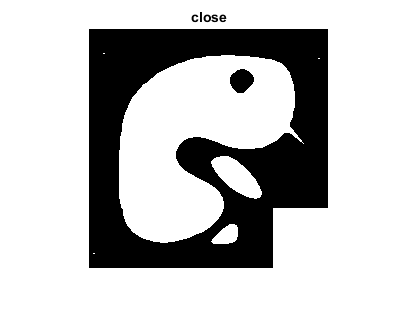

figure,imshow(cl),title('close')

## Dilatació condicional

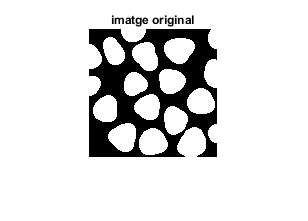

im=imread('blob3.tif');
figure,imshow(im),title('imatge original')

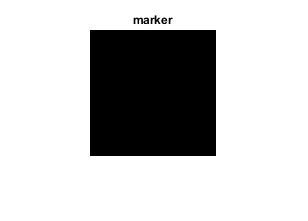

mark=true(128);
mark(2:end-1,2:end-1)=0;
figure,imshow(mark),title('marker')

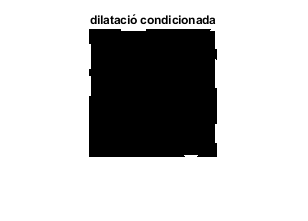

ee=strel('disk',1);
dilc=imdilate(mark,ee)&im;
figure,imshow(dilc),title('dilatació condicionada')

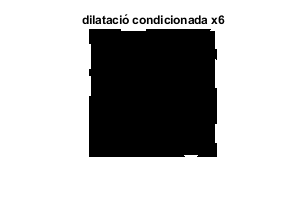

dilc=imdilate(mark,ee)&im;
dilc=imdilate(mark,ee)&im;
dilc=imdilate(mark,ee)&im;
dilc=imdilate(mark,ee)&im;
dilc=imdilate(mark,ee)&im;
dilc=imdilate(mark,ee)&im;
figure,imshow(dilc),title('dilatació condicionada x6')

## Reconstrucció amb marc

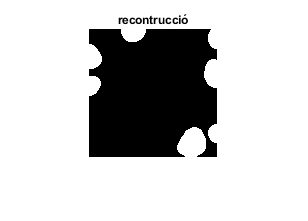

rec=imreconstruct(mark,im);
figure,imshow(rec),title('recontrucció')

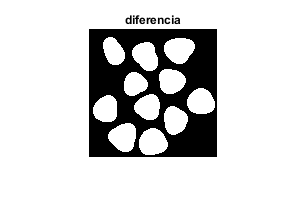

im2 = xor(rec,im);
figure,imshow(im2),title('diferencia')

## Exercici 2:

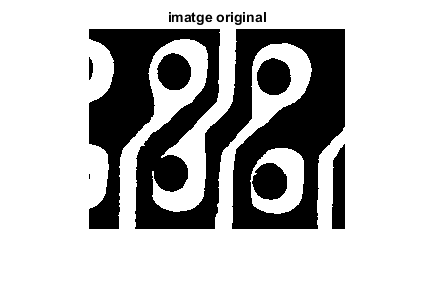

im=imread('pcbholes.tif');
figure,imshow(im),title('imatge original')

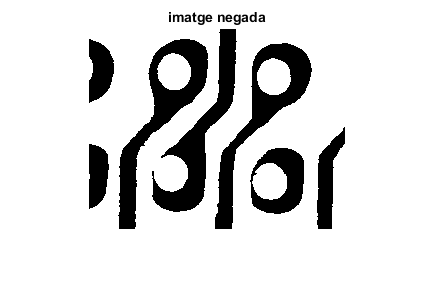


% Creem el marc amb el tamany de la imatge original
mark=true(200,256);
mark(2:end-1,2:end-1)=0;

% Neguem la imatge
im2=imcomplement(im);
figure,imshow(im2),title('imatge negada')

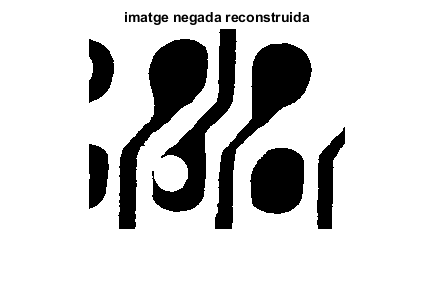


% Reconstruim a partir del marc, la imatge negada. S'eliminen els forats
rec=imreconstruct(mark,im2);
figure, imshow(rec),title('imatge negada reconstruida')

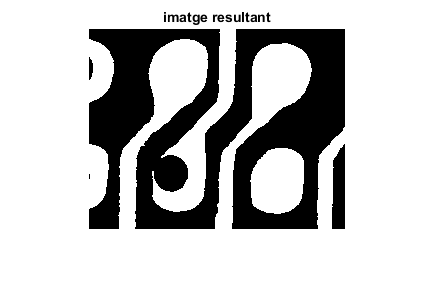


% Tornem a negar el resultat obtingut, d'aquesta manera, veiem que els
% forats ja no existeixen si comparem amb la imatge original
res=imcomplement(rec);
figure, imshow(res),title('imatge resultant')

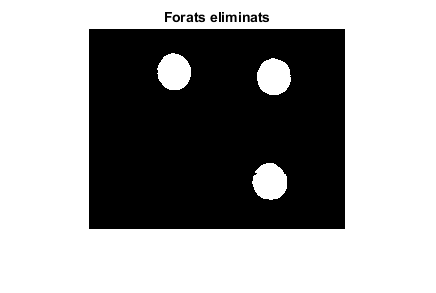


% La diferència entre la imatge original i el resultat serà els forats
% eliminats
dif=res-im;
figure,imshow(dif),title('Forats eliminats')

## Reconstrucció amb ee

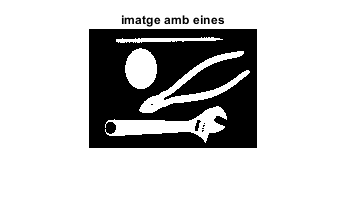

im=imread('tools.tif');
figure,imshow(im),title('imatge amb eines')

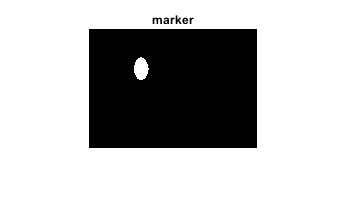

ee=strel('disk',9);
ero=imerode(im,ee);
figure,imshow(ero),title('marker')

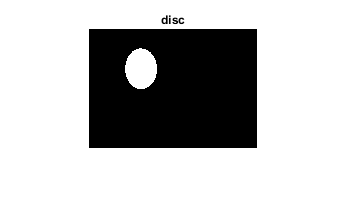

rec1=imreconstruct(ero,im);
figure,imshow(rec1);title('disc')

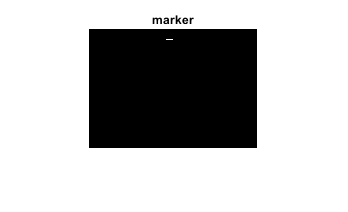

ee=strel('line',100,0);
ero=imerode(im,ee);
figure,imshow(ero),title('marker')

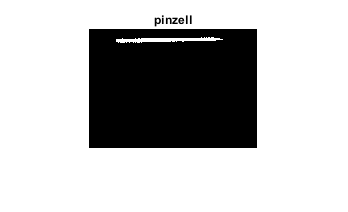

rec2=imreconstruct(ero,im);
figure,imshow(rec2);title('pinzell')

## Exercici 3

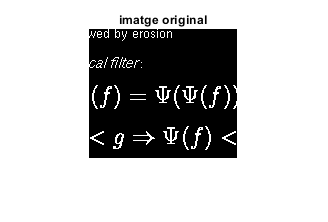

% Mantenir només la lletra Ψ de la imatge original

im=imread('letters.tif');
figure, imshow(im),title('imatge original')

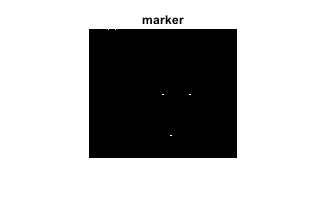


% Seleccionem les lletres que tenen almenys una línia vertila de 17 píxels
ee=strel('line',17,90);
ero=imerode(im,ee);
figure, imshow(ero), title('marker')

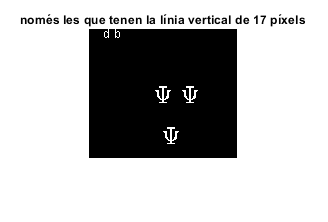

rec2=imreconstruct(ero,im);
figure,imshow(rec2),title('només les que tenen la línia vertical de 17 píxels')

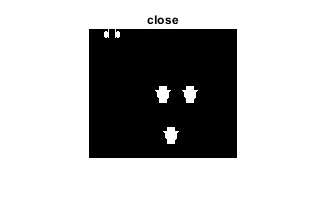


% Fem un close per engreixar les lletres obtingudes
ee1=strel('disk', 1);
close=imclose(rec2,ee);
figure, imshow(close),title('close')

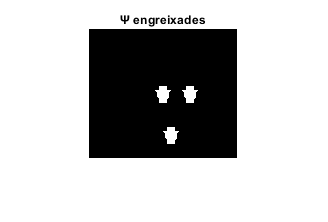


% Amb la diferència d'area amb un disc de radi 4, podem excluir les lletres
% 'b' i 'd'
ee2=strel('disk',4);
ero=imerode(close,ee2);
rec3=imreconstruct(ero,close);
figure,imshow(rec3),title('Ψ engreixades')

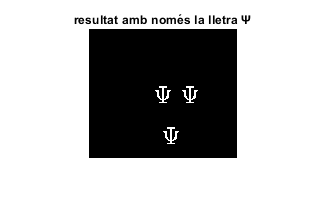


% Finalmente, amb una and de la imatge del close i la de les Ψ engreixades,
% trobarem únicament els símbols Ψ
res = and(rec3,rec2);
figure, imshow(res), title('resultat amb només la lletra Ψ')